clear, close, clc

% Constants
mu = astroConstants(13);

% Data
rA = 10000;
alpha = 0.1:0.1:30;
beta = 0.1:0.1:100;
[ alpha, beta ] = meshgrid( alpha, beta );

k = 1;
for i = 1:size(alpha,1)
    for j = 1:size(alpha,2)

        if alpha(i,j) == beta(i,j)
            r(k,1) = alpha(i,j);
            r(k,2) = beta(i,j);
            k = k + 1;
        end

    end
end


% Radius
rB = beta*rA;
rC = alpha*rA;

% Velocities
dV_Hohmann = 1./sqrt(alpha) - sqrt(2) .* (1 - alpha) ./ sqrt( alpha .* ( 1 + alpha ) ) - 1;
dV_Biell = sqrt(2 .* ( alpha + beta ) ./ ( alpha .* beta) ) - ( 1 + sqrt(alpha)) ./ sqrt( alpha ) - sqrt( 2 ./ ( beta .* ( 1 + beta) ) ) .* ( 1 - beta);
dV_Biell_dV_H = dV_Hohmann ./ dV_Biell;

% Plot
figure
[C,h] = contour( alpha, beta, dV_Biell_dV_H, 'Levellist', 1 );
hold on
grid on
plot(r(:,1), r(:,2), 'r--', 'linewidth', 3)
clabel(C,['manual', ''])

 
    Please wait a moment...
 
   Carefully select contours for labeling.
   When done, press RETURN while the Graph window is the active window.


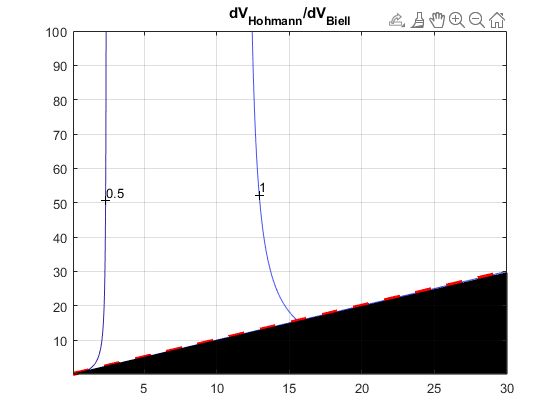

fill([alpha(1),alpha(end),alpha(end)], [beta(1),beta(1),r(end,2)], [0,0,0])
title('dV_{Hohmann}/dV_{Biell}')